# Delayed Feedback System for Franka Emika Panda

Add Path

clear;clc;
addpath("..\ReadYAML\")
addpath("Visualization\")
config=ReadYaml("Configuration\FrankaEmikaPanda.yaml");

The system follows


$$M\left(\vec{q} (t)\right) \ddot{\vec{q}} (t) + G \left( \vec{q} (t) \right) = - K_{p} \left( \vec{q} \left( t - \frac{3}{2} t_{s} \right) - \vec{q}_{d} \right) - K_{d} \dot{\vec{q}} \left( t - \frac{3}{2} t_{s} \right) - f \left( \dot{\vec{q}} \right),$$


where friction follows


$$f^{j} (\dot{q})= \frac{\varphi_{1,j}}{1 + e^{- \varphi_{2,j} \left( \dot{q}_{j} + \varphi_{3,j} \right)}} - \frac{\varphi_{1,j}}{1 + e^{- \varphi_{2,j} \varphi_{3,j}}}.$$


## Configurations

Dimension

config_mapping.dimension=7;

Precision and truncation rank

config_mapping.precision=30;
config_mapping.trunc_rank=-1;

Target Position

config_mapping.target=config.TargetAngle';

Gains

config_mapping.K_p=diag(config.Kp);
config_mapping.K_d=diag(config.Kd);

Matrix Expontent Method

config_mapping.MatExpOpt="jordan";

Visualization of rank of $\mathcal{A}^i$

config_mapping.visual_Acal_rank=50;

## Discretization

Start Computing M_d
历时 0.179594 秒。
Done
Start Computing K_G
历时 0.880198 秒。
Done
Start Computing K_f
历时 0.005806 秒。
Done
Start Computing A
历时 0.059047 秒。
Done


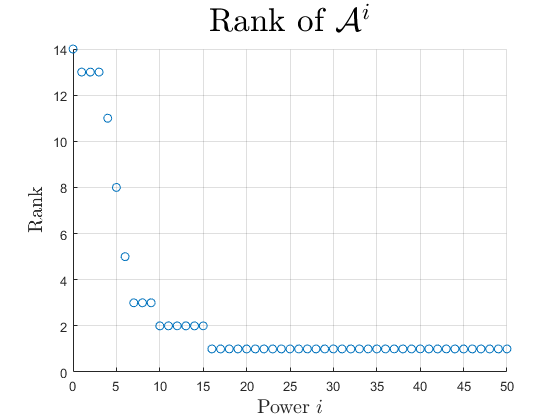

Start Computing B
历时 57.407394 秒。
Done
Start Compiling W
历时 0.002223 秒。
Done


ts=3.308e-3; % Stable when approximation at 1e-3
% ts=7.87e-3;
result_discretization=DiscreteMapping(ts,config_mapping);

## Visualization

Eigen Properties

eig_data=eig(result_discretization.W,"balance","vector");
eig_data=round(eig_data*1000)/1000;
% eig_data=vpa(eig_data,5)

$$eig\_data = \left(\begin{array}{c} 0.48217\\ 0.82678\\ 0.99076+0.026373\,\mathrm{i}\\ 0.99076-0.026373\,\mathrm{i}\\ 0.9887+0.023254\,\mathrm{i}\\ 0.9887-0.023254\,\mathrm{i}\\ 0.98686+0.019651\,\mathrm{i}\\ 0.98686-0.019651\,\mathrm{i}\\ 0.98209+0.014338\,\mathrm{i}\\ 0.98209-0.014338\,\mathrm{i}\\ 0.99454\\ 1.0005\\ 0.99986\\ 0.017105\\ 0.017024\\ 0.017263\\ 0.0010209+0.00030058\,\mathrm{i}\\ 0.0010209-0.00030058\,\mathrm{i}\\ 0.0046932\\ 0.0069985\\ 0.0061386 \end{array}\right)$$

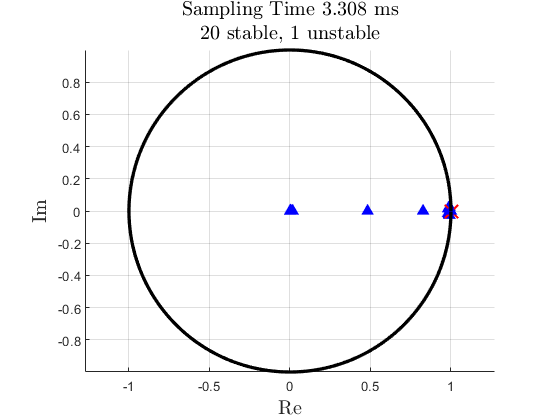

show_eig(eig_data, true, ts)

disp(vpa(eig_data,config_mapping.precision))

$$\left(\begin{array}{c} 0.482165357746794143167790025473\\ 0.826781691323844825092237442732\\ 0.990761633253214313299395143986+0.0263731921772034638706827536225\,\mathrm{i}\\ 0.990761633253214313299395143986-0.0263731921772034638706827536225\,\mathrm{i}\\ 0.988698727946029976010322570801+0.0232537434704696011067426297814\,\mathrm{i}\\ 0.988698727946029976010322570801-0.0232537434704696011067426297814\,\mathrm{i}\\ 0.986864630681793641997501254082+0.0196514008239141446665598778054\,\mathrm{i}\\ 0.986864630681793641997501254082-0.0196514008239141446665598778054\,\mathrm{i}\\ 0.982090280979036833741702139378+0.0143379710533899640267918584868\,\mathrm{i}\\ 0.982090280979036833741702139378-0.0143379710533899640267918584868\,\mathrm{i}\\ 0.994540964719590192544274032116\\ 1.00049998048370980541221797466\\ 0.999864285286776066641323268414\\ 0.0171045575204757938081456813961\\ 0.0170236364529117167876393068582\\ 0.017262621909402753317408496514\\ 0.00102091354903133257892022811575+0.000300579093262920427065409967327\,\mathrm{i}\\ 0.00102091354903133257892022811575-0.000300579093262920427065409967327\,\mathrm{i}\\ 0.0046932439035325401732734462712\\ 0.0069985431471364378808175388258\\ 0.00613855056816703381628030911088 \end{array}\right)$$

Norm of $W^i \vec{v}$

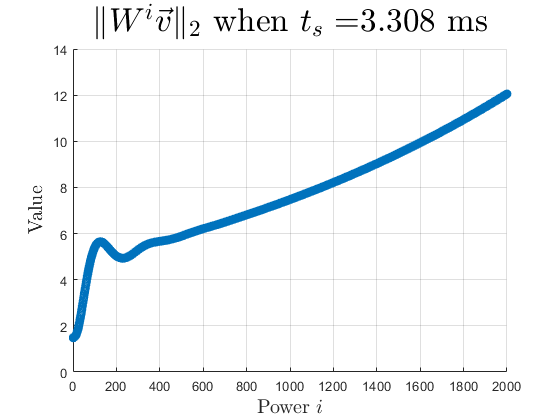

vec_test=0.01*ones(21,1);
modulus_data=zeros(2000,1);
for i=1:length(modulus_data)
    modulus_data(i)=norm(mpower(result_discretization.W,i)*vec_test);
end
scatter(1:length(modulus_data),modulus_data)
grid on
title("$\Vert W^{i} \vec{v} \Vert_{2}$ when $t_s=$" + ...
    num2str(1000*ts)+" ms", "FontSize",25,"Interpreter","latex")
xlabel("Power $i$","Interpreter","latex","FontSize",15)
ylabel("Value","Interpreter","latex","FontSize",15)